%% Model definition
m= 1000; %kg, mass of the vehicle
I=1500; %kgm^2, moment of inertia of the vehicle
a=1.5; %m, distance from the center of mass to the front axle
b=1.5; %m, distance from the center of mass to the rear axle
c=1; % The distance from the center of mass to the left/right side of the tires (y axis)
parameters=[m;I;a;b;c];
%% 
V=5;
eps_0=[0;
    0.0;
    V];
u0=[0.0;0];
Ts=1e-2;
% Define model, cost function, and bounds.
sys=simp_discreteSS(eps_0,u0,parameters,Ts);
A = sys.A;
B = sys.B;

% computes a control invariant set for LTI system x^+ = A*x+B*u

system = LTISystem('A', A, 'B', B);
xlb = [-10; -10;-100];
xub = [10;10;100];
ulb = [-100; -100];
uub=-ulb;
system.x.min = xlb;
system.x.max = xub;
system.u.min = ulb;
system.u.max = uub;
Q=diag([30,0.1,1]);
R=eye(2)*0.1;
system.x.penalty = QuadFunction(Q);
system.u.penalty = QuadFunction(R);
%TODO: kijken welke van de 2 we nodig hebben
% InvSet = system.invariantSet() 
InvSet = system.LQRSet()
InvSet.plot('color','blue')

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Polyhedron in R^3 with representations:
    H-rep (irredundant) : Inequalities  20 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


xlabel('Y')
ylabel('\psi')
zlabel('V')
title('Terminal set')

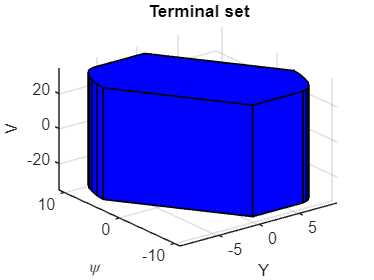

A_u=[-1 0;

    1 0;
    0 -1;
    0 1;];
b_u=[100;
    100;
    100;
    100;];
P_u=Polyhedron(A_u,b_u)
P_u.plot()
xlabel('\delta')

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


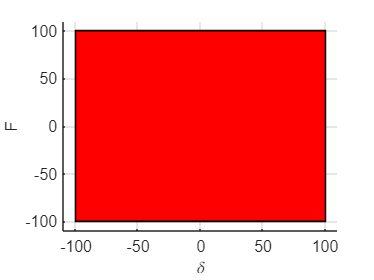

ylabel('F')

## Assumptions:

### Controllability

% eig(A)
% eig(A-B*K)
% rank(ctrb(A,B)) 

Rank 

### 2.2: Continuity of system and cost:

The functions $f:\mathbb{Z}\to \mathbb{X}:\mathbb{l}$

Stage cost for LQR:


$$l\left(x,u\right)=x^T \textrm{Qx}+u^T \textrm{Ru}$$


Terminal cost for LQR: $V_f \left(x\left(N\right)\right)={x\left(N\right)}^T P^{\infty } x\left(N\right)$

- 
$$f\left(0,0\right)=0$$


- 
$$l\left(0,0\right)=0$$


- 
$$V_f \left(0\right)=0$$


### 2.3: Properties of constraint sets. 

The set $\mathbb{Z}\;$is closed and the setr ${\mathbb{X}}_f \subseteq \mathbb{X}\;\textrm{is}\;\textrm{compact}\ldotp$ Each set contains the origin. This is proved using the sets. (plot)

% x_var=sdpvar(3,1);
% interval=[xlb<=x_var<=xub];
% X_set=YSet(x_var,interval)
% X_set.plot()

### 2.14: Basic stability assumption

Vf, Xf and l have the following properties:

- for all $x\in {\mathbb{X}}_f ,$there exists a u (such that $\left(x,u\right)\in \mathbb{Z}$ satisfying

- 
$$f\left(x,u\right)\in {\mathbb{X}}_f$$


- 
$$V_f \left(f\left(x,u\right)\right)-V_f \left(x\right)\le l\left(x,u\right)$$


Because it is known that $V_N^0 \left(x\right)\ge l\left(x,\kappa_N \left(x\right)\right)$ for all $x\in X_N$, the

%NEXT: Create LQR controller
%Calculate LQR gains and create system
[K,P]=dlqr(A,B,Q,R)

K =    15.9038    9.8115   -0.0000
    0.0000    0.0000    3.1374


P =   370.1577  103.9267    0.0000
  103.9267   61.5673    0.0000
    0.0000    0.0000   63.7475


lqrsys=LTISystem('A',A-B*K,'B',B)

LTISystem with 3 states, 2 inputs, 0 outputs


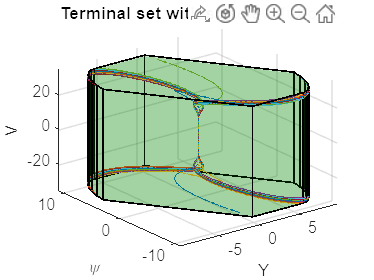

Vert=InvSet.V; %Edges of set
N=500;

    
x_ts=zeros(size(Vert,1),N,3);
for i=1:size(Vert,1) %Loop over all vertices
    x0=Vert(i,:);
    lqrsys.initialize(x0);
    for j=1:N  
        x_ts(i,j,:)=lqrsys.update(zeros(2,1));

            
    end
    xN=x_ts(i,j,:);
    xN=xN(:);
    if InvSet.A*xN<=InvSet.b %Constraint equality
                % disp('No problem at with step from x0 to x{N}:')
                % [x0
                % x_ts(i,j,:)']
    else
                disp(["Ax<=b does not hold at x= ",xN'])
                % disp(x_ts(i,j,:));
                % [x0
                 % newx']
    end %Zero because control is the feedback law implemented

    % disp([x0;xN])
end
figure
InvSet.plot('color','green','alpha',0.2)
hold on
for i=1:size(Vert,1)
    quiver3(x_ts(i,1:end-1,1),x_ts(i,1:end-1,2),x_ts(i,1:end-1,3),diff(x_ts(i,:,1)),diff(x_ts(i,:,2)),diff(x_ts(i,:,3)));
end
xlabel('Y')
ylabel('\psi')
zlabel('V')
title('Terminal set with state evolutions');
% axis equal
hold off

%Check for all sets in inv_set.V if Ax<=b holds after state update

### Lyapunov decrease

x_lyap=[x_ts(1,:,1);
    x_ts(1,:,2);
    x_ts(1,:,3)]
V_f = zeros(N-1,1);

x_lyap =    -0.5768   -0.9556   -1.2623   -1.5041   -1.6881   -1.8208   -1.9086   -1.9573   -1.9724   -1.9590   -1.9218   -1.8649   -1.7922   -1.7072   -1.6129   -1.5120   -1.4069   -1.2996   -1.1920   -1.0854   -0.9812   -0.8803   -0.7836   -0.6917   -0.6050   -0.5239   -0.4486   -0.3792   -0.3156   -0.2578   -0.2057   -0.1590   -0.1176   -0.0810   -0.0492   -0.0217    0.0018    0.0216    0.0380    0.0513    0.0618    0.0699    0.0758    0.0797    0.0820    0.0828    0.0824    0.0810    0.0787    0.0758
   -8.3333   -6.8177   -5.4496   -4.2238   -3.1344   -2.1744   -1.3362   -0.6118    0.0070    0.5287    0.9615    1.3137    1.5932    1.8077    1.9646    2.0708    2.1330    2.1571    2.1489    2.1134    2.0555    1.9795    1.8891    1.7879    1.6789    1.5647    1.4477    1.3299    1.2129    1.0983    0.9870    0.8801    0.7784    0.6822    0.5922    0.5084    0.4310    0.3600    0.2954    0.2371    0.1847    0.1381    0.0970    0.0611    0.0299    0.0033   -0.0192   -0.0379   -0.0532

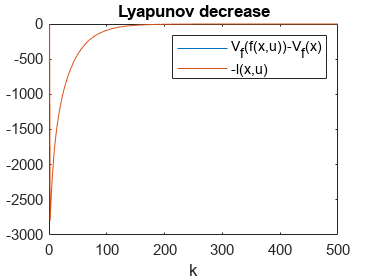

L_x = zeros(N-1,1);
for k = 2:N
    V_f_d = x_lyap(:,k)'*P*x_lyap(:,k)-x_lyap(:,k-1)'*P*x_lyap(:,k-1);
    l_xu = x_lyap(:,k-1)'*Q*x_lyap(:,k-1)+(-K*x_lyap(:,k-1))'*R*(-K*x_lyap(:,k-1));
%     l_xu = x_lyap(:,k-1)'*Q*x_lyap(:,k-1);
    V_f(k,:) = V_f_d;
    L_x(k,:) =  -l_xu;
    
end

figure 

plot(V_f,'DisplayName','V_f');
hold on
plot(L_x,'DisplayName','l(x)');
legend('V_f(f(x,u))-V_f(x)','-l(x,u)');
title('Lyapunov decrease');
xlabel('k');
hold off
figure

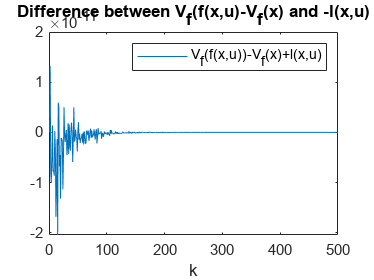

plot(V_f-L_x);
title('Difference between V_f(f(x,u)-V_f(x) and -l(x,u)')
legend('V_f(f(x,u))-V_f(x)+l(x,u)');
xlabel('k')


% x_lyap=x_lyap(:,:)

### 2.17:


$$$$


## Means 2.22 holds